#      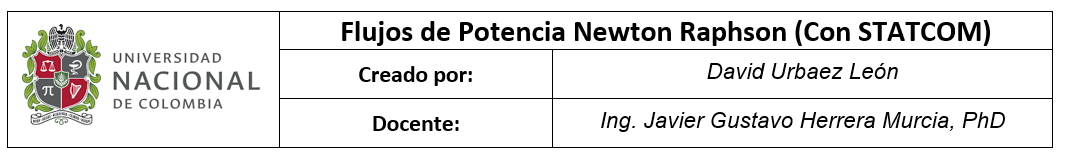

clc; clear all; close all

### 1)    Se definen las bases del sistema

-  Potencia base $S_b ={100\cdot 10}^{6\;}$[VA]

-  Voltaje base   $V_b ={230\cdot 10}^{3\;}$[V]

Sb = 100e6; %[VA]
Vb = 230e3; %[V]

### 2)    Se crean las matrices  con la información de la red ( br_data, N_data):

Se deben crear dos matrices para ingresar la información referente al circuito. La primera (br_data) brinda información acerca de las conexiones entre buses como la impedancia de la línea o los buses entre los cuales se realiza la conexión , mientras que la segunda (N_data) da información acerca de la naturaleza de cada uno de los buses, tipo de bus (SL, PV o PQ).

a) Para la matriz **br_data** se tiene que el formato es

                    
$$\mathrm{br}_\mathrm{data}=\left\lbrack {\mathrm{Bus}}_{\mathrm{from}\;} ,{\mathrm{Bus}}_{\mathrm{to}} ,R,X,G,B\right\rbrack \;\mathrm{in}\;p\ldotp u\ldotp$$


b) Para la matriz **N_data **se tiene que el formato es:

                  
$$N_‾‾\mathrm{data}=\left\lbrace \mathrm{#Bus},\mathrm{type}\left(\prime \mathrm{SL}\prime ,\prime \mathrm{PQ}\prime ,\prime \mathrm{PV}\prime \right),V\left\lbrack p\ldotp u\ldotp \right\rbrack ,\angle \mathrm{Vº},\mathrm{PG}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{QG}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{PL}\left\lbrack p\ldotp u\ldotp \right\rbrack ,\mathrm{QL}\left\lbrack p\ldotp u\ldotp \right\rbrack \right\rbrace$$


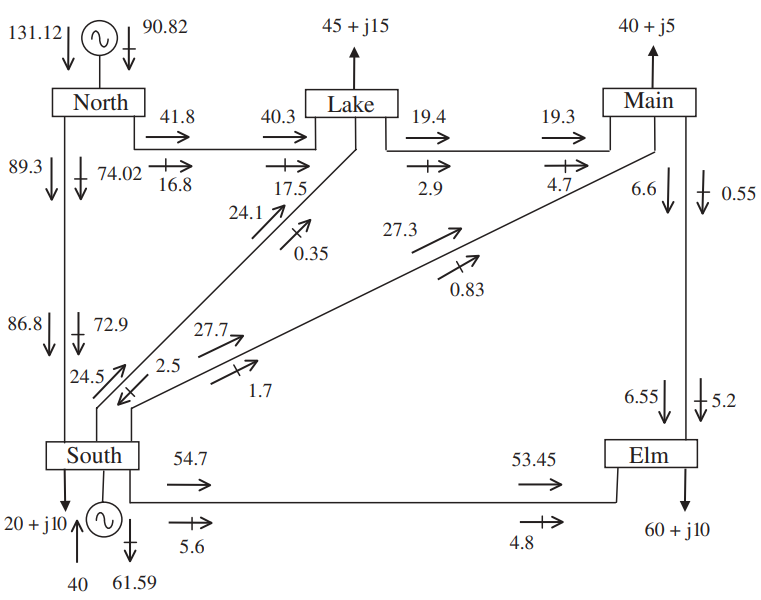

% Branches data R, X, G, B
% Types: General in form of impedance. (G & B are split in half at both ends).

% br_data=[ bus1, bus2,     R,     X,     G,      B] in p.u.
br_data = [
            1,      2,  0.02,    0.06,    0.0,    0.06;
            1,      3,  0.08,    0.24,    0.0,    0.05;
            2,      3,  0.06,    0.18,    0.0,    0.04;
            2,      4,  0.06,    0.18,    0.0,    0.04;
            2,      5,  0.04,    0.12,    0.0,    0.03;
            3,      4,  0.01,    0.03,    0.0,    0.02;
            4,      5,  0.08,    0.24,    0.0,    0.05];

% Node definitions
% {  #, type,   Vpu,    <Vº,   PG pu,  QG pu,  PL pu, QL pu}
N_data = {
    1,  'SL',   1.06,   0.0,    0.0,    0.0,    0.00,    0.00;
    2,  'PV',   1.0,    0.0,    0.4,    0.0,    0.20,    0.10;
    3,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.45,    0.15;
    4,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.40,    0.05;
    5,  'PQ',   1.0,    0.0,    0.0,    0.0,    0.60,    0.10;  };

br_data=array2table(br_data,'VariableNames',{'FromBus','ToBus','R','X','G','B'});
N_data=cell2table(N_data,'VariableNames',{'n','type','Vm','Va','PG','QG','PL','QL'});

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% STATIC SYNCHRONOUS COMPENSATOR (STATCOM)
% NSSC : Number of STATCOM’s
% SSCsend: STATCOM’s bus
% Xvr : Converter’s reactance (p.u.)
% TarVol: Target nodal voltage magnitude (p.u.)
% VSta : Indicate the control status over nodal voltage magnitude: 1 is
% on; 0 is off
% Psp : Target active power flow (p.u.)
% PSta : Indicate the control status over active power: 1 is on; 0 is off
% Qsp : Target reactive power flow (p.u.)
% QSta : Indicate the control status over reactive power:1 is on; 0 is off
% Vvr : Initial condition for the source voltage magnitude (p.u.)
% Tvr : Initial condition for the source voltage angle (deg)
% VvrHi : Lower limit source voltage magnitude (p.u.)
% VvrLo : higher limit source voltage magnitude (p.u.)

% SSC_data= [SSCsend, Xvr , TarVol , VSta, Psp , PSta , Qsp , QSta,Vvr,Tvr,VvrHi,VvrLo];
SSC_data  = [    3  , 0.1 ,    1   ,   1 ,  0  ,   1  ,   0 ,   0 , 1 , 0 , 1.1 , 0.9 ];

SSC_data=array2table(SSC_data,'VariableNames',{'SSCsend',' Xvr ',' TarVol ',' VSta',' Psp ',' PSta ',' Qsp ',' QSta','Vvr','Tvr','VvrHi','VvrLo'})

SSC_data = 1×12 table
    SSCsend    Xvr    TarVol    VSta    Psp    PSta    Qsp    QSta    Vvr    Tvr    VvrHi    VvrLo
    _______    ___    ______    ____    ___    ____    ___    ____    ___    ___    _____    _____

       3       0.1      1        1       0      1       0      0       1      0      1.1      0.9 


Run_STATCOM_PowerFlow

### 7) Se presentan los resultados obtenidos

PrintResults(Vn,SGn,SLn,k,err,num_nodes,N_data)

     ******************************************** 
     **          Newton-Raphson Results        ** 
     ******************************************** 

-- Number of Iterarions: 5 
-- Error: 5.385e-15 p.u.

	Node#	Type	V p.u.	 ∠V(º)	PG p.u.	QG p.u.	PL p.u.	QL p.u.
--------------------------------------------------------------------
   	1	SL	 1.060	 0.000	 1.311	 0.853	 0.000	 0.000	
   	2	PV	 1.000	-2.053	 0.400	-0.771	 0.200	 0.100	
   	3	PQ	 1.000	-4.838	 0.000	 0.205	 0.450	 0.150	
   	4	PQ	 0.994	-5.107	 0.000	 0.000	 0.400	 0.050	
   	5	PQ	 0.975	-5.797	 0.000	 0.000	 0.600	 0.100	


array2table(S_pf,'VariableNames',{'FromBus','ToBus','P','Q','S'});

### 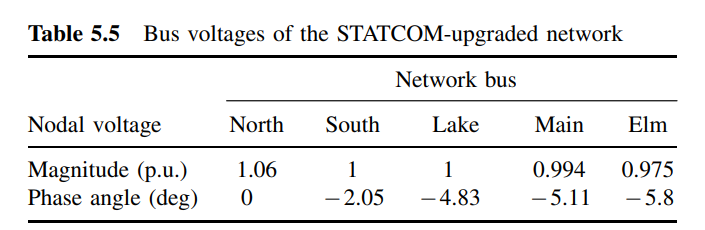

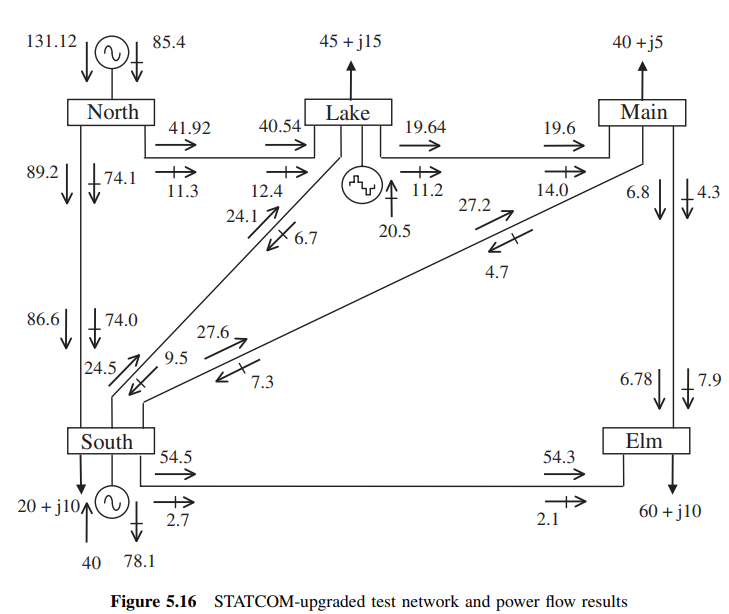

### Referencias:

[1] Gomez - Exposito,A. Electrica Energy Systems, Analysis and operation. 2nd Edition. Boca Raton : Taylor & Francis, CRC Press, 2018.

[2] Acha,E. FACTS Modelling and Simulation in Power Networks. 1st Edition. Boca Raton : John Wiley & Sons Inc,2004 

[3] Zhang, X.P, Flexible AC Transmission Systems: Modelling and Control, Berlin: Springer, 2006.